clear;
global SAVE_EXT;
global SAVE_DIR;
SAVE_EXT = ".png";% figure saving conf (png, eps, etc...)
SAVE_DIR = "./tex/images/";
% addpath("../CVX-arm64/");
% cvx_setup;
mkdir(SAVE_DIR);


k_1 = 7.29;
a_0_1 = 1;
T_1 = 0.38;
xi = 0;
k_2 = 9.46;
a_0_2 = 1;
T_2 = 1;
T = 0.25;
A_g = 7.68;
omega_g = 0.3;

## Task 1

TF_plant = tf([k_2], [T_2, a_0_2]) * tf([k_1], [T_1, a_0_1]);
ss_plant_continious = ss(TF_plant);
poles_ss_plant_continious = pole(ss_plant_continious);
ss_plant_discrete = c2d(ss_plant_continious, T)

ss_plant_discrete =
 
  A = 
            x1       x2
   x1   0.3581  -0.2104
   x2   0.3198   0.9387
 
  B = 
           u1
   x1  0.1599
   x2  0.0466
 
  C = 
          x1     x2
   y1      0  1.245
 
  D = 
       u1
   y1   0
 
Sample time: 0.25 seconds
Discrete-time state-space model.


eig(ss_plant_discrete.A)

ans =     0.5179
    0.7788


Gamma = [0 1; 0 0];
H = [1 1];
assert(rank(ctrb(ss_plant_discrete.A, ss_plant_discrete.B)) == 2);
assert(rank(obsv(Gamma, H)) == 2);
model_disc = c2d(ss(Gamma, [0; 0], H, 0), T);
eig(Gamma), eig(model_disc.A)

ans =      0
     0


ans =      1
     1


M = sylvester(ss_plant_discrete.A, -Gamma, ss_plant_discrete.B * H);
K = H * inv(M)

K =     4.8975   11.0238


ss_plant_discrete.A - ss_plant_discrete.B * K, eig(ss_plant_discrete.A - ss_plant_discrete.B * K)

ans =    -0.4250   -1.9729
    0.0915    0.4250


ans = 1.0e-08 *

   -0.5460
    0.5460


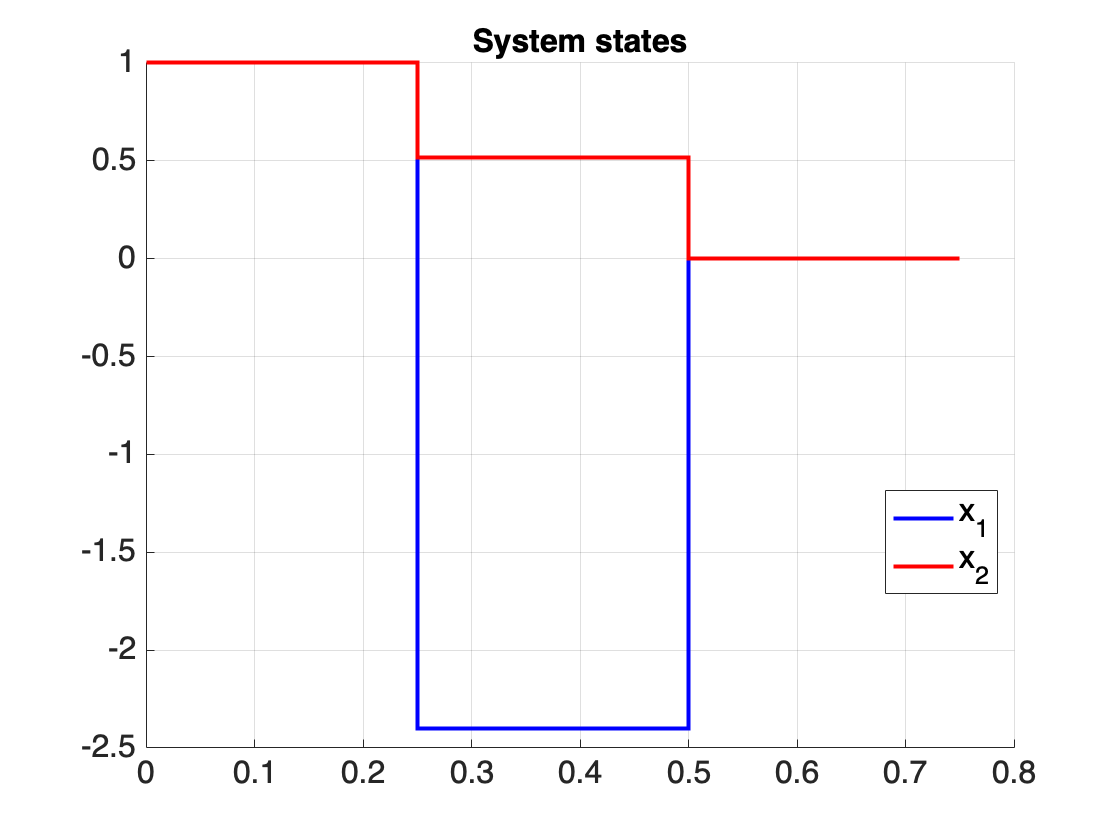

sim_res = sim("task1.slx", 0.75);
clf;
title("System states");
hold on;
stairs(sim_res.x.time, sim_res.x.data(:,1), 'LineWidth', 2, 'Color', 'blue', 'LineStyle', '-');
stairs(sim_res.x.time, sim_res.x.data(:,2), 'LineWidth', 2, 'Color', 'red', 'LineStyle', '-');
grid on;
legend({'x_1', 'x_2'}, 'Location', 'best');
fontsize(16, "points");
hold off;
exportgraphics(gcf, SAVE_DIR + "task1" + SAVE_EXT);

## Task 2

A_gen = [0 omega_g; -omega_g 0];
ss_gen = ss(A_gen, [0; 0], [A_g 0], 0);
ss_gen_disc = c2d(ss_gen, T)

ss_gen_disc =
 
  A = 
             x1        x2
   x1    0.9972   0.07493
   x2  -0.07493    0.9972
 
  B = 
       u1
   x1   0
   x2   0
 
  C = 
         x1    x2
   y1  7.68     0
 
  D = 
       u1
   y1   0
 
Sample time: 0.25 seconds
Discrete-time state-space model.


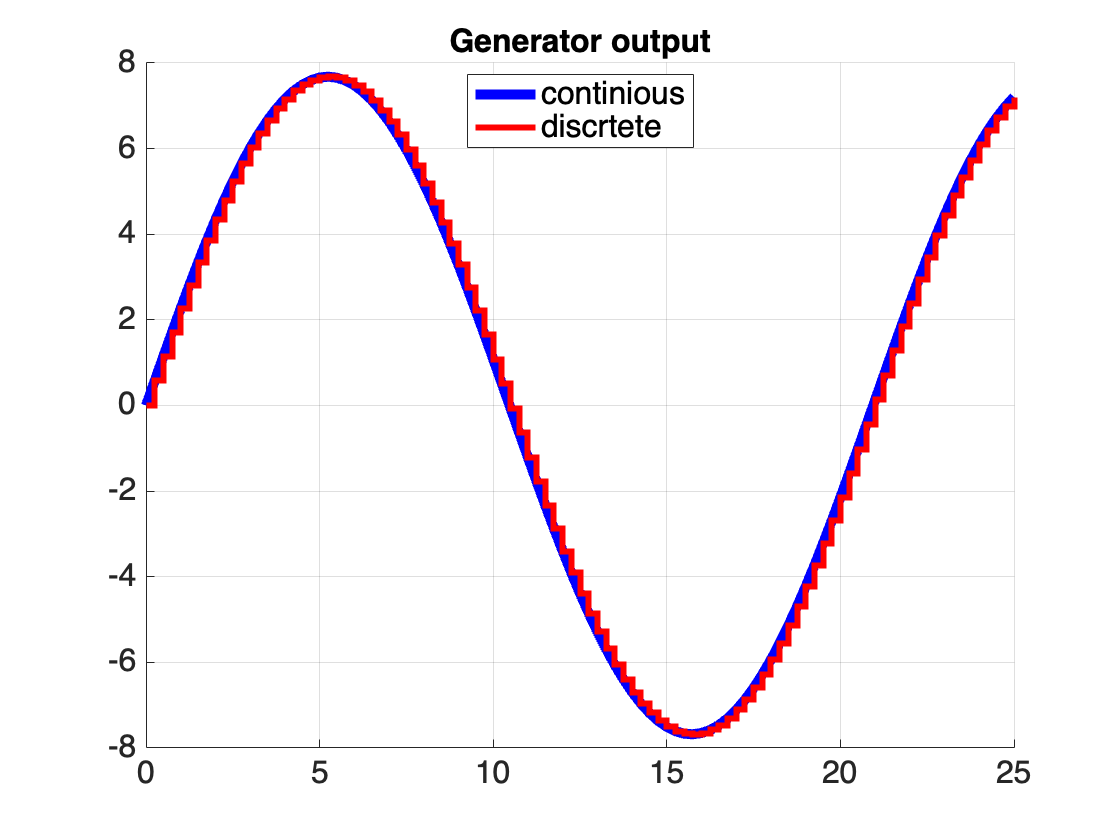

sim_res = sim("task2.slx", 25);
clf;
title("Generator output");
hold on;
plot(sim_res.gen_c.time, sim_res.gen_c.data, 'LineWidth', 5, 'Color', 'blue', 'LineStyle', '-');
stairs(sim_res.gen_d.time, sim_res.gen_d.data, 'LineWidth', 3, 'Color', 'red', 'LineStyle', '-');
grid on;
legend({'continious', 'discrtete'}, 'Location', 'best');
fontsize(16, "points");
hold off;
exportgraphics(gcf, SAVE_DIR + "task2_generator" + SAVE_EXT);

ss_obsv = compreal(ss_plant_discrete, "o")

ss_obsv =
 
  A = 
            x1       x2
   x1        0        1
   x2  -0.4034    1.297
 
  B = 
          u1
   x1  4.229
   x2  8.608
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Sample time: 0.25 seconds
Discrete-time state-space model.


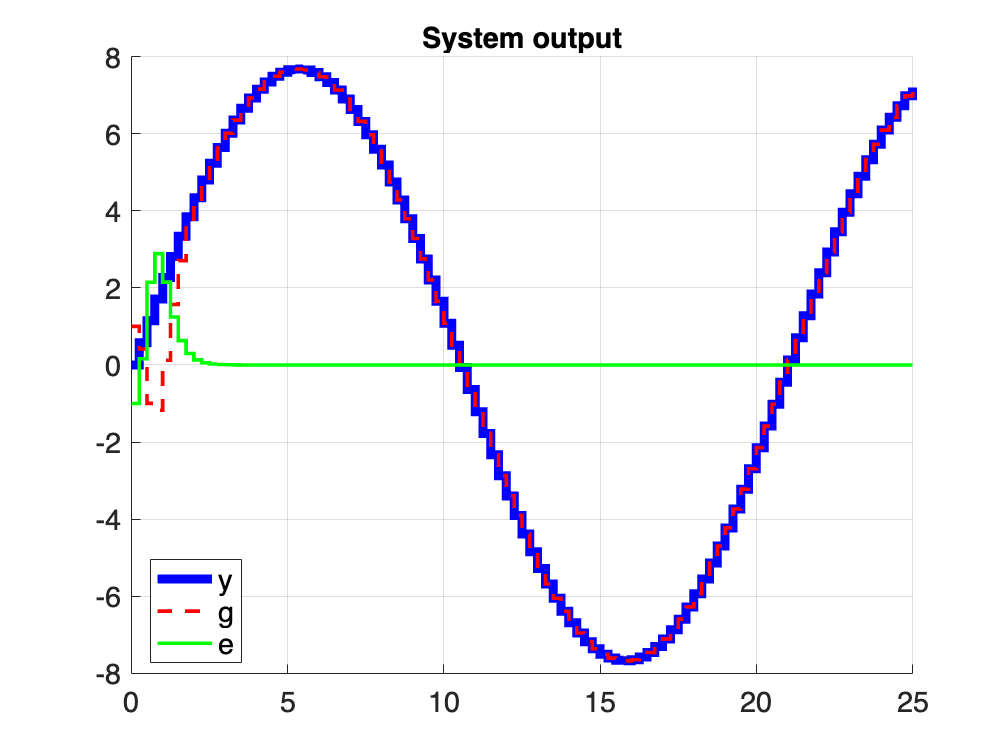

B_eta = [1; 1];
assert(rank(ctrb(ss_gen_disc.A, B_eta)) == 2);
Gamma = ss_gen_disc.A;

A_bar = [Gamma -B_eta * ss_obsv.C; zeros(2, 2) ss_obsv.A];
B_bar = [0; 0; ss_obsv.B];
B_1_bar = [B_eta; 0; 0];
K_bar = place(A_bar, B_bar, [0.1 0.2 0.3 0.4]);
B_g_bar = B_1_bar + K_bar(1) * B_bar;

F_bar = A_bar - B_bar * K_bar;

sim_res = sim("task2.slx", 25);
clf;
title("System output");
hold on;
stairs(sim_res.gen_d.time, sim_res.gen_d.data, 'LineWidth', 5, 'Color', 'blue', 'LineStyle', '-');
stairs(sim_res.y.time, sim_res.y.data, 'LineWidth', 2, 'Color', 'red', 'LineStyle', '--');
stairs(sim_res.y.time, sim_res.gen_d.data - sim_res.y.data, 'LineWidth', 2, 'Color', 'green', 'LineStyle', '-');
grid on;
legend({'y', 'g', 'e'}, 'Location', 'best');
fontsize(16, "points");
hold off;
exportgraphics(gcf, SAVE_DIR + "task2_system" + SAVE_EXT);

A_bar, B_bar, K_bar, eig(A_bar - B_bar * K_bar)

A_bar =     0.9972    0.0749   -1.0000         0
   -0.0749    0.9972   -1.0000         0
         0         0         0    1.0000
         0         0   -0.4034    1.2967


B_bar =          0
         0
    4.2286
    8.6085


K_bar =    -0.3568    0.1592    0.1383    0.1982


ans =     0.4000
    0.3000
    0.2000
    0.1000


## Task 3